## Définition du mouvement

% Vitesse du mobile
vmax = 0.5;  % m/s

% accélération du mobile
amax = 5; % m/s²

% Position initiale
x_i = 0; % mm
y_i = 0; % mm
theta_i = 0; % rad

% Position finale
x_f = 500; % mm
y_f = 600; % mm
theta_f = 0; % rad

distance = sqrt(x_f^2+y_f^2);
 

## Définition des constantes

% Hauteur mobile
% Largeur mobile
% Rayon du tambour
R_t = 25; % mm
% Temps d'échantillonnage
dt = 0.001 ;

## Définition des lois en trapèze de vitesse

[les_t,les_x,les_v,les_a] = calcule_profil(amax,vmax,distance,dt);
plot(les_t,les_x,les_t,les_v,les_t,les_a/5 )
xlabel('Temps (s)');
grid on;
legend('Position [m]', ...
    'Vitesse [m/s]', ...
    'Accélération [m/s²] /5')

### Tracé de la trajectoire du mobile sur l'espace de travail

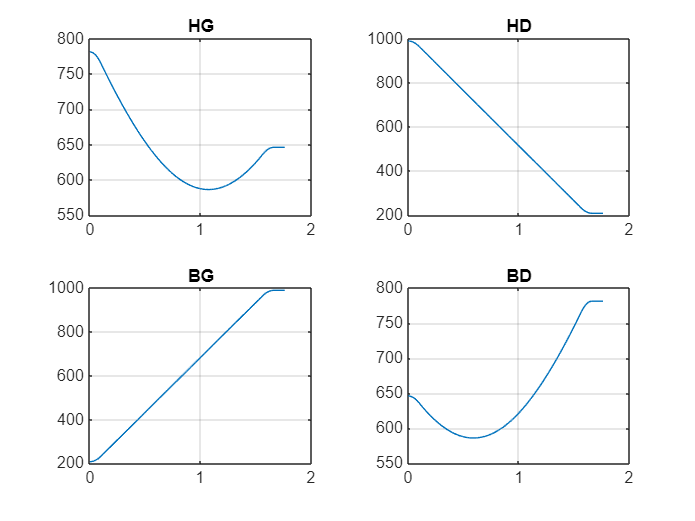

[les_t,les_xm,les_ym] = trajectoire_mobile(x_i,y_i,x_f,y_f,amax,vmax,dt);
% ZONE DE TRAVAIL A VERIFIER
xt = [-50,550,550,-50,-50];
yt = [-25,-25,625,625,-25];

plot(les_xm,les_ym,xt,yt)%,label = "Position mobile");
grid on;
xlabel('Xm [mm]');
ylabel('Ym [mm]');
legend("Déplacement du mobile","Zone de travail")

### Déplacement du mobile

plot(les_t,les_xm, les_t,les_ym )
grid on
xlabel('Temps (s)');
legend("X machine [mm]","Y machine[mm]")

### Tracé de la longueur des câbles

#### Calcul des longueurs

% les_BG = [get_L_phi(les_xm[i],les_ym[i],0,"BG")[1] for i in range(len(les_xm))]
% les_BD = [get_L_phi(les_xm[i],les_ym[i],0,"BD")[1] for i in range(len(les_xm))]
% les_HG = [get_L_phi(les_xm[i],les_ym[i],0,"HG")[1] for i in range(len(les_xm))]
% les_HD = [get_L_phi(les_xm[i],les_ym[i],0,"HD")[1] for i in range(len(les_xm))]

les_bg = [];
les_bd = [];
les_hg = [];
les_hd = [];
for i =1:length(les_xm)
    [bg,phi] = get_L_phi(les_xm(i),les_ym(i),0,"BG");
    [bd,phi] = get_L_phi(les_xm(i),les_ym(i),0,"BD");
    [hg,phi] = get_L_phi(les_xm(i),les_ym(i),0,"HG");
    [hd,phi] = get_L_phi(les_xm(i),les_ym(i),0,"HD");
    les_bg(end+1) = bg;
    les_bd(end+1) = bd;
    les_hg(end+1) = hg;
    les_hd(end+1) = hd;
end

#### Tracé

tiledlayout(2,2)

nexttile
plot(les_t,les_hg)
grid on
title("HG")

nexttile
plot(les_t,les_hd)
grid on
title("HD")

nexttile
plot(les_t,les_bg)
grid on
title("BG")

nexttile
plot(les_t,les_bd)
grid on
title("BD")

#### Conversion en points

les_hg_qc = 8192*les_hg/R_t/2/pi;
plot(les_t,les_hg_qc)